root = 'data\load-cell-calibration\5lb';

files = dir([root '\*.mat'])

files = 11×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum



g = 9.82;

mean_output = [];
loads = [];
for i=1:length(files)
    file = [files(i).folder '\' files(i).name];
    load(file);

    i_end = find(files(i).name == 'g')-1;
    loads(end+1) = (str2double(files(i).name(1:i_end))/1000)*g;
    mean_output(end+1) = mean(data);
end

[p S] = polyfit(mean_output, loads, 1);
disp(['Slope (a): ' num2str(p(1))])

Slope (a): 2.4064


disp(['Intercept (b): ' num2str(p(2))])

Intercept (b): -0.21754



% Evaluate Fit
y_fit = polyval(p, mean_output);

% Calculate R-squared
residuals = loads - y_fit;
ss_res = sum(residuals.^2); % Sum of Squares Residuals
ss_tot = sum((loads - mean(loads)).^2); % Total Sum of Squares
r2 = 1 - (ss_res / ss_tot);
disp(['R-squared: ' num2str(r2)]);

R-squared: 0.99977


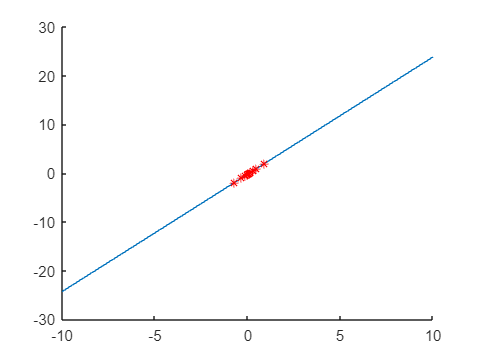


virtual_input = linspace(-10,10,500);

figure;
hold on
plot(virtual_input,p(1)*virtual_input+p(2))

plot(mean_output,loads,'r*')
hold off

root = 'data\load-cell-calibration\100g';

files = dir([root '\*.mat'])

files = 9×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum



g = 9.82;

mean_output = [];
loads = [];
for i=1:length(files)
    file = [files(i).folder '\' files(i).name];
    load(file);

    i_end = find(files(i).name == 'g')-1;
    loads(end+1) = (str2double(files(i).name(1:i_end))/1000)*g;
    mean_output(end+1) = mean(data);
end

[p S] = polyfit(mean_output, loads, 1);
disp(['Slope (a): ' num2str(p(1))])

Slope (a): 0.11029


disp(['Intercept (b): ' num2str(p(2))])

Intercept (b): -0.0045775



% Evaluate Fit
y_fit = polyval(p, mean_output);

% Calculate R-squared
residuals = loads - y_fit;
ss_res = sum(residuals.^2); % Sum of Squares Residuals
ss_tot = sum((loads - mean(loads)).^2); % Total Sum of Squares
r2 = 1 - (ss_res / ss_tot);
disp(['R-squared: ' num2str(r2)]);

R-squared: 0.9981


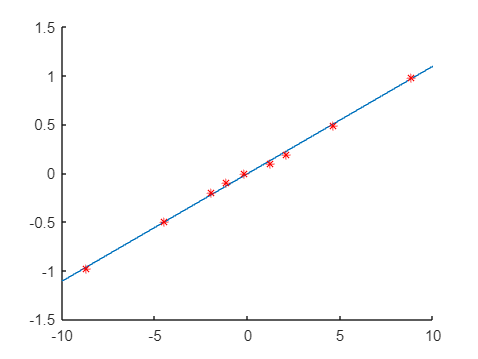


virtual_input = linspace(-10,10,500);

figure;
hold on
plot(virtual_input,p(1)*virtual_input+p(2))

plot(mean_output,loads,'r*')
hold off